clear
close all
clc
delete(gcp('nocreate'))
tic

DIR='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/';

%% Load constants and functions
addpath(DIR)
Const=Constants;
fDIR=[DIR 'Functions/'];
addpath(fDIR)


## calculate r_min, r_max

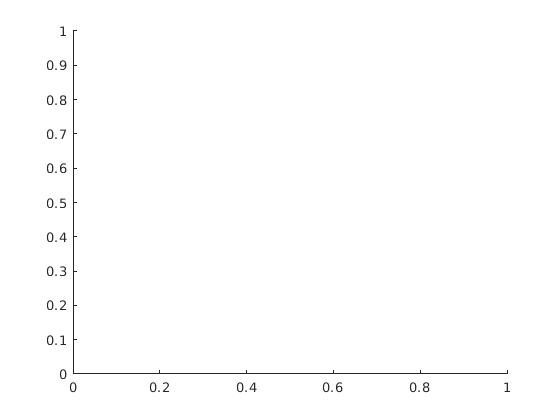


A=0.0001:0.000025:0.02;
rinitmax=15;
step=10^(-6);
rdommax=Const.rs:step:Const.ri;
rdommin=Const.ri:step:rinitmax;
rmax=zeros(size(A));
rmin=rmax;
%parpool('local',12)
for j=1:numel(A)
     hold on
    [~,J]=max(krzywa(rdommax,A(j)));
    rmax(j)=rdommax(J);
    rdommin_next=rdommin;
    [~,I]=min(krzywa(rdommin_next,A(j)));
    rmin_temp=rdommin_next(I);
    p=1;
    while I==numel(rdommin_next)
        p=p+1;
        rdommin_next=rdommin_next(I):step:(2*rdommin_next(I));
         [~,I]=min(krzywa(rdommin_next,A(j)));
         rmin_temp(p+1)=rdommin_next(I);
    end
    rmin(j)=rmin_temp(end);
end

## plot

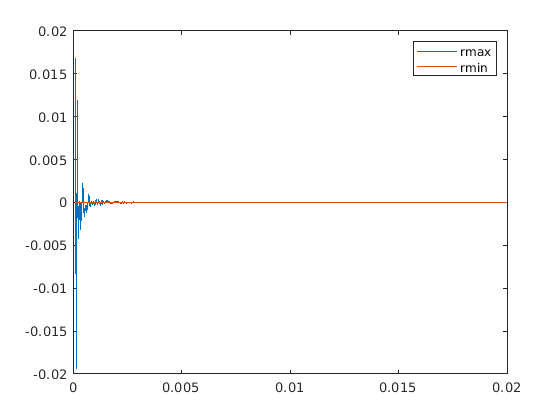

clf
plot(A,(A-sqrt(fi(rmax)))./A)
hold on
plot(A,(A-sqrt(fi(rmin)))./A)

legend('rmax','rmin')


%ylabel('\sqrt(\phi(r))','interpreter','latex')
x=A-sqrt(fi(rmin));

function wartosc=krzywa(r,A)
wartosc=r.*A.*sqrt(1+((1-exp(-r.^2/2))./(2*pi*A*r.^2)).^2);
end

function wart=fi(r)
part1=(1-exp(-r.^2/2))./r.^2;
part3=exp(-r.^2/2);
wart=part1.*(part1-part3)/(2*pi)^2;
end